# Senzory a Měření - protokol 5 - odporové senzory teploty

Vypracoval **Vojtěch Michal** 13. dubna 2021, "měření" provedeno dle videa ze dne 6.4. 2020.

Záznam z měření na Youtube:

[https://www.youtube.com/watch?v=e16w7iuc8OM](https://www.youtube.com/watch?v=e16w7iuc8OM) [https://www.youtube.com/watch?v=-zmH5pZOvUY](https://www.youtube.com/watch?v=-zmH5pZOvUY) [https://www.youtube.com/watch?v=ymAUrlvtmbc](https://www.youtube.com/watch?v=ymAUrlvtmbc) [https://www.youtube.com/watch?v=93CG0Ax7mmg](https://www.youtube.com/watch?v=93CG0Ax7mmg) [https://www.youtube.com/watch?v=GqJlxhnKxFY](https://www.youtube.com/watch?v=GqJlxhnKxFY)

Návod k úloze na Moodle: [https://moodle.fel.cvut.cz/pluginfile.php/279158/mod_resource/content/2/11_odporovy%20senzor%20teploty_2019_v2.pdf](https://moodle.fel.cvut.cz/pluginfile.php/279158/mod_resource/content/2/11_odporovy%20senzor%20teploty_2019_v2.pdf)

## Poznámky

Datcon DT1010 (https://cdn.papouch.com/data/user-content/old_eshop/files/DAT_DT1010Pt100IA/dt1010_cz.pdf) je průmyslový převodník odporu (pro nás třeba úměrný teplotě měřené senzorem Pt100) na různé výstupy (primárně analogově napětí/proud, případně USB). Řídicí software obsahuje možnost vyčítat data z převodníku a souběžně nastavovat parametry výstupního signálu, jenž může být zpracováván nějakým dalším průmyslovým zařízením. Například podporuje nastavení dolní a horní meze výstupu pro minimální a maximální teplotu, na výstup dává napětí vypočtené lineární interpolaci měřené teploty mezi dané hranice. Tím má uživatelsky konfigurovatelnou posunutou nulu. 

Úhrnný radiační pyrometr - bezkontaktní měření termodynamické teploty pomocí infračerveného záření. *Úhrnný == *integruje intenzitu přes všechny vlnové délky (srovnej s jednopásmovým). Pro velmi přesné měření (např měření teploty těla v souvislosti s koronou) vyžaduje velmi přesnou kalibraci a nastavení emisivity, jak vidět v úloze 1. Organické materiály mají obecně poměrně vysokou emisivitu blízkou jedničce (viz úloha 5).

*Posunutá nula *převodníku (viz úloha 3) indikuje schopnost kompenzovat nějaký známý konstantní offset. Např Pt100 má při 0°C úbytek $U_o = I_{meas} \cdot 100\Omega$; když výstup převodníku posuneme o tento konstantní offset, například budeme moci efektivněji využít vstupní rozsah ADC.

Použitá Pt100 v kovovém krytu má relativně pomalou dynamiku (viz úloha 4), nedá se použít na měření rychlých změn, je ale velmi robustní. Senzor s odkrytým koncem by měl dynamiku výrazně rychlejší (prohřívání tenkého platinového drátku), ale byl by náchylný na mechanické poškození. Nikdy nepouštět vyšší proud než $\approx$1mA kvůli nežádoucímu zahřívání v důsledku tekoucího měřicího proudu. Souvisí se *zatěžovací konstantou* D pro senzor, jež dává do souvislosti ztrátový výkon a chbu měření.

## Domácí příprava

V zadání výše jsou obrázky zapojení odkazované jako obr. 1 a obr. 2. Pro zapojení 1 (dvouvodičové zapojení Pt100 s pounutou nulou) platí $U_2 = -U_Z \cdot \frac{\Delta R}{2R_0}$.

- Pro jakou teplotu je U2 = 0 V v případě použití převodníku s posunutou nulou dle obr. 1 (senzor Pt 100, $R_0 = 100 \Omega$? **Odpověď**: Pro $U_2 = 0V \rightarrow \Delta R = 0\Omega \rightarrow R_{Pt100} = R_0 = 100 \Omega$ a tento odpor má senzor právě pro 0°C.

- Jaké referenční napětí UZ je třeba nastavit, aby na výstupu bylo napětí U2 = 100 mV pro teplotu 100 °C (platinový odporový teploměr, $R_0 = 100 \Omega$)? **Odpověď: **Při teplotě 100°C má senzor $\Delta R = 39 \Omega$, proto úpravou vztahu výše $U_Z = -U_2 \cdot \frac{2R_0}{\Delta R} = -0.1 \frac{2 \cdot 100}{39} =  -0.513 V$.

- Lze korigovat v tomto případě vliv odporu přívodních vodičů? **Odpověď: **Zapojení je v principu třívodičové (invertující svorkou neteče proud, takže je to vlastně sense kanál), ale obecně v takto jednoduchém zapojení odpor přívodů kompenzovat nelze.

- Jak velká bude chyba měření teploty vzniklá vlivem změny odporu přívodů o 0,1 Ω ? **Odpověď**: Největší chyba nastane při teplotě 0°C, protože tehdy by mělo být $U_2 = 0V$, a sice $\frac{0.1}{39 / 100} = 0.25 °C$.

- Jaký proud prochází senzorem Pt100 v případě zapojení na obr. 1 a obr. 2? Závisí tento proud na měřené teplotě? **Odpověď: **Obě zapojení jsou z hlediska odporového senzoru zdroje konst proudu. V případě 1 teče proud $I_{meas} = \frac{U_Z}{2R_0}$, v případě druhém $I_{meas} = \frac{6.58 V}{10k\Omega} = 0.6 \text{mA}$.

## Úkoly měření

### 1) Proveďte kalibraci bezkontaktního teploměru pomocí vyhřívaného etalonu BB2-A

Při emisivitě $\epsilon = 0.95$ měřeno 139.1 °C. Pro $\epsilon = 0.88$ měřeno 145.4°C. Přepočet intenzity na termodynamickou teplotu je podle Stefan Boltzmannova zákona $I = \epsilon \sigma (T^4 - T_A^4)$, odtud je tedy teplota nepřímo měřena jako $T = \sqrt[4]{\frac{I}{\sigma \epsilon} + T_A^4}$. Podle přednášky [https://moodle.fel.cvut.cz/pluginfile.php/279131/mod_resource/content/4/SME_prednaska_09_teplota9_v3.pdf](https://moodle.fel.cvut.cz/pluginfile.php/279131/mod_resource/content/4/SME_prednaska_09_teplota9_v3.pdf) slide 38 platí $\frac{\text{d}T}{T} = -0.25 \frac{\text{d}\epsilon}{\epsilon$, tento vztah dává horní odhad na chybu termodynamické teploty. Protože relativní chyba emisivity je $\frac{\text{d}\epsilon}{\epsilon} = \frac{0.95 - 0.88}{0.95} = 7.37\%$, je relativní chyba termodynamické teploty $\frac{\text{d}T}{T} = 1.84\%$, odtud očekávaná absolutní chyba $\Delta T = \frac{1.84}{100} \cdot (139.1 + 273.15) = 7.59 K$. Měřená absolutní chyba je $145.4 - 139.1 = 6.3 K$, očekávaná hodnota tak velmi dobře odpovídá.

### 2) Použijte dvouvodičové připojení téhož odporového snímače teploty a zjistěte, jakou chybu to způsobí.

Senzor teploty Pt100 ve speciálním módu multimetru Agilent 34410A na měření teploty (čtyřsvorkové měření a digitální přepočet na teplotu) ukazuje 22.90°C. Měřicí proud podle [https://www.keysight.com/us/en/assets/7018-01326/data-sheets/5989-3738.pdf](https://www.keysight.com/us/en/assets/7018-01326/data-sheets/5989-3738.pdf) má pro odpory kolem 100 $\Omega$ velikost 1mA DC.

Režim měření odporu lze mít dvousvorkový i čtyřsvorkový. Změřené odpory senzoru Pt100 v pícce vyšší teploty: dvousvorkově 109.59 $\Omega$, čtyřsvorkově 108.92 $\Omega$. Čtyřsvorkové měření očekáváme nižší, protože se neuplatní žádné odpory přívodních vodičů. Pro Pt100 je měřicí proud třeba $I =1$mA, kterou multimetr udržuje proudovým zdrojem, takže nezáleží na odporu silových vodičů. Na sense vodičích je naopak voltmetr s vysokým vnitřním odporem. Naopak při dvousvorkovém měření pouštíme měřicí proud do seriové kombinace $R_v + R_{Pt100} + R_v$, vzniká tedy (pro konstantní měřicí proud) konstatní chyba $2R_v$.

Odpor přívodů $R_v$ lze měřit ohmmetrem přiloženým mezi silový a sense vodič na téže straně senzoru. Změřeno $2R_v = 0.666\Omega$, což číselně přes odpovídá rozdílu hodnot pro dvou a čtyřsvorkové měření. Pro Pt100 platí $R_{Pt100} = 100 \Omega$ pro 0°C, $R_{Pt100} = 138.5\Omega$ pro 100°C, to je $\frac{138.5 - 100}{100} = 0.385 \Omega \cdot °C^{-1}$ a čtyřsvorkové měření tak vnáší konstatní offset 1.73 °C.

Seriově připojený stejnosměrný ampérmetr U3401A potvrdil velikost měřicího proudu 1mA, sám má podle datasheetu [https://www.keysight.com/zz/en/assets/7018-02145/data-sheets/5990-3970.pdf](https://www.keysight.com/zz/en/assets/7018-02145/data-sheets/5990-3970.pdf) vnitřní odpor pro range 5mA velikosti 100 $\Omega$, Agilent proto v daném uspořádání měří 210 $\Omega$, což odpovídá součtu odporu Pt100 a vodičů, shuntu v rezistoru a případně dalšího půl ohmu někde na konektorech. Střídavý proud je měřen 0A, Agilent tedy střídavým proudem odpor **ne**měří. Měřicí proud je v rámci rozlišovací schopnosti ampérmetru konstantní.

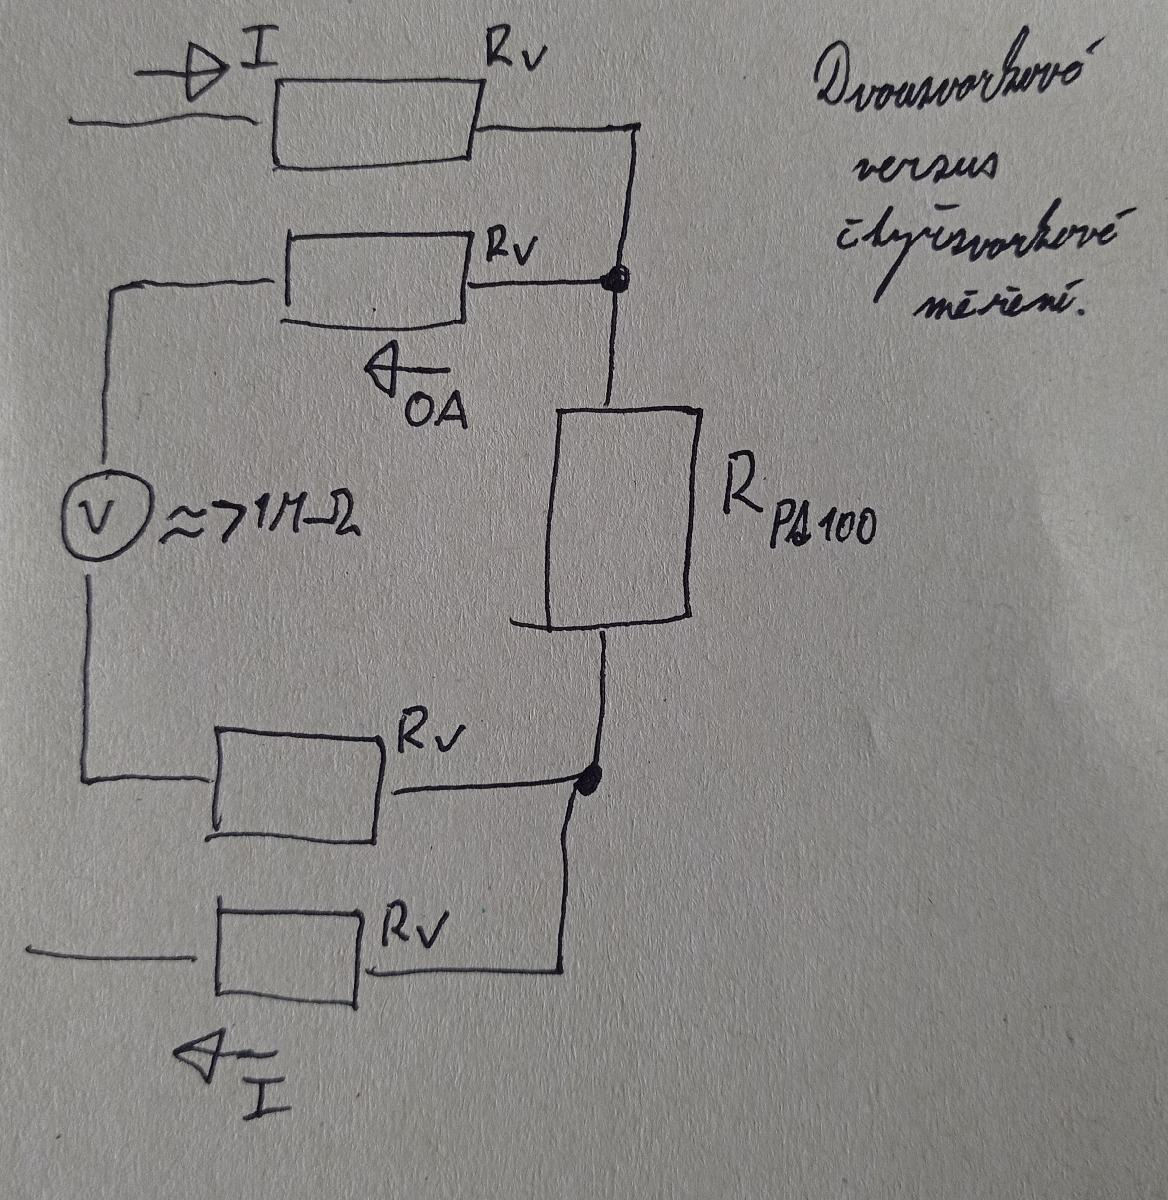

### 3) Teplotu vyhřívaného etalonu BB2-A dále změřte týmž odporovým teploměrem připojeným k převodníku R/U s posunutou nulou.

Zapojení viz zadání, obrázek 1. Použito $U_z = - 0.52 V$, pokojový teploměr měří teplotu 147°C. Multimetr Agilent měří 148.2 mV, převodník s OZ má převodní charakteristiku 1mV na 1°C, odtud měřená teplota 148.2°C. 

### 4) Změřte teplotu vyhřívaného etalonu BB2-A týmž odporovým teploměrem připojeným k modulu s USB rozhraním DT1010.

Použitím seriově připojeného ampérmetru lze určit, že DT1010 měří na rozsahu proudem 0.85 mA stejnosměrně. Směr proudu není potřeba komutovat na rozdíl od většiny můstkových měření, kde se měří výrazně menší napětí a je proto potřeba kompenzovat i termoelektrické napětí. 

Skoková změna teploty je z 23.8°C (teplota laboratoře) na aktuálně nastavených 147°C etalonu. Přechod 23.8°C $\rightarrow$ 101.5°C za 22 s (odečteno z časové osy videa), to je 63% ustálení. Hrubým odhadem by tak senzor mohl mít časovou konstantu 25 vteřin.

Při čtyřvodičovém měření je na sense svorkách 134.87 mV (změřeno multimetrem), to při známém měřícím proudu odpovídá odporu senzoru $R = \frac{134.87}{0.85} = 158.67 \Omega$, ke kterému náleží teplota:

R0 = 100;Rmeas = 158.67; A = 3.9e-3; B = -5.8e-7;
coefs = [R0 * B,  R0 * A, R0-Rmeas];

coefs =    -0.0001    0.3900  -58.6700


roots(coefs) % kořen 154 °C, druhý kořen 6570 nedává smysl.

ans = 	1.0e+03 *

    6.5702
    0.1540
